# Well Test Interpreter

The main idea is to generate a simple well test interpreter of data of pressure and rates in time of a well.

This project was developed in a course of Well Testing at Politecnico di Torino.

The file example with the structure of the data is called "Pressure&Rate.txt".

Future versions are intented to include:

- Automatization of some processes.

- An app in python to do the process easier.

- Include convolution (Potentially?).

Leonardo Arana Parodi

leonardo.arana.parodi@gmail.com

August, 2025

# 1. Import data

close all
clear all
filename = 'Pressure&Rate.txt';
delimiter = ' ';
startRow = 3;
formatSpec = '%f%f%f%f%[^\n\r]';

%% Open the text file.
fileID = fopen(filename,'r');
textscan(fileID, '%[^\n\r]', startRow-1, 'ReturnOnError', false);
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'ReturnOnError', false);

%% Close the text file.
fclose(fileID);
%% Allocate imported array to column variable names
rate = dataArray{:, 1};
t = dataArray{:, 2};
p = dataArray{:, 4};
%% Clear temporary variables
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

# 2. General Data

API=25;
mu=0.002; %[Pa*s] =2 [cp]
Bo=1.22; %[m3/m3]
Ct=4.35*10^(-10); %[Pa^-1]=4.35*10^(-5) [1/bara]
Pi=200; %[barg] @gauge depth
Tr=60; %[°C]@gauge depth
depth=1990; %[mssl]
rw=0.1; %[m]
h=10; %[m]
phi=0.2;
qdd1=50/(24*60*60); %[stdm3/sec]
qdd2=100/(24*60*60); %[stdm3/sec]
flow_periods=4;

# 3. Plot the data

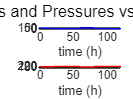

%Plotting
figure
sgtitle('Rates and Pressures vs time')
subplot(2,1,1)
plot(t/(60*60), rate,'-b')
xlabel('time (h)')
ylabel('rate (stdm3/d)')
ylim([(min(rate)) (max(rate))*1.2])
subplot(2,1,2)
plot(t/(60*60), p,'-r')
xlabel('time (h)')
ylabel('pressure (barg)')
ylim([(min(p)) (max(p))*1.1])

# 3. Manage the data

%Manage the data
Data=[t rate p*100000]; %data for calculations (time in seconds and Press. in Pa)
%Separation of 4 flow periods and 3 matrix for time, rates and pressures:
i=1;
b=1;
c=1;
while rate(i)>0
    timem(c,b)=Data(i,1);
    ratem(c,b)=Data(i,2);
    pressm(c,b)=Data(i,3);
    c=c+1;
    i=i+1;
end
b=b+1;
c=1;
while rate(i)==0
    timem(c,b)=Data(i,1);
    ratem(c,b)=Data(i,2);
    pressm(c,b)=Data(i,3);
    c=c+1;
    i=i+1;
end
b=b+1;
c=1;
while rate(i)>0
    timem(c,b)=Data(i,1);
    ratem(c,b)=Data(i,2);
    pressm(c,b)=Data(i,3);
    c=c+1;
    i=i+1;
end
b=b+1;
c=1;

while i<=length(Data) & rate(i)==0
    timem(c,b)=Data(i,1);
    ratem(c,b)=Data(i,2);
    pressm(c,b)=Data(i,3);
    c=c+1;
    i=i+1;
end
%Obtain tps and rates of the flow periods:
tps(1)=max(timem(1, :)); %time of production 1
rates(1)=(ratem(2, 1)/(24*60*60)); %rate of production 1
lengths(1)=length(find(timem(:, 1)))+1; %length of data
tps(2)=max(timem(:,2))-max(timem(:, 1));
rates(2)=(ratem(2, 2)/(24*60*60));
lengths(2)=length(find(timem(:, 2)));
tps(3)=max(timem(:, 3))-max(timem(:, 2));
rates(3)=(ratem(2, 3)/(24*60*60));
lengths(3)=length(find(timem(:, 3)));
tps(4)=max(timem(:, 4))-max(timem(:, 3));
rates(4)=(ratem(2, 4)/(24*60*60));
lengths(4)=length(find(timem(:, 4)));


# 4. Calculations for DD1

Using the following equations:


$$\Delta p\left(t\right)=p_i -p_{\textrm{wf}} \left(t\right)$$



$${\Delta p\left(t_i \right)}^{\prime } =\frac{\Delta p\left(i+1\right)-\Delta p\left(i\right)}{\textrm{lnt}\left(i+1\right)-\textrm{lnt}\left(i\right)}$$


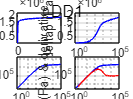

%Calculation of deltap, lnt and deltap' for DD1
deltap=[];
lnt=[];
derivative=[];
deltap(:, 1)=(pressm(1,1)-pressm(2:lengths(1),1)); %(Pi-pwf)...from 2 to final...length: -1 of press data
lnt(:,1)=log(timem(2:lengths(1),1)); %(from second term in order to have the same length as deltap)
for a = 1:(lengths(1)-2) %length: -1 of deltap and lnt and -2 of press data
       derivative(a,1)=(deltap(a+1, 1)-deltap(a,1))/(lnt(a+1, 1)-lnt(a, 1)); %2 to (final-1)...length -1 of deltap and lnt and -2 of press
end

%Plotting
figure

set (gca,'ydir','reverse');
sgtitle('DD1')
subplot(2,2,1)
plot(timem(2:lengths(1), 1), deltap(:,1),'-b')
xlabel('time (s)')
ylabel('deltap (Pa)')
ylim([(min(deltap(:,1))) (max(deltap(:,1)))*1.2]);

subplot(2,2,2)
semilogx(timem(2:lengths(1), 1), deltap(:,1),'-b')
grid on
xlabel('time (s)')
ylabel('deltap (Pa)')
ylim([(min(deltap(:,1))) (max(deltap(:,1)))*1.2]);

subplot(2,2,3)
loglog(timem(2:lengths(1), 1),deltap(:,1),'-b')
grid on
xlabel('time (s)')
ylabel('deltap (Pa)')
ylim([(min(deltap(:,1))) (max(deltap(:,1)))*10]);


subplot(2,2,4)
loglog(timem(2:lengths(1), 1), deltap(:,1),'-b')
hold on
loglog(timem(3:lengths(1), 1), derivative(:,1),'-r')
grid on
xlabel('time (s)')
ylabel('deltap (Pa) & derivative')
ylim([(min(deltap(:,1))) (max(deltap(:,1)))*10]);

# 5. Calculations for FP>1

## Calculation of ST and deltap for each flow period

Using the following equations:

Superposition Time of DD


$$\textrm{ST}=\prod_{i=1}^n {\left(t-T_{i-1} \right)}^{\frac{q_i -q_{i-1} }{q_n }}$$


Superposition Time of BU


$$\textrm{ST}=\prod_{i=1}^n {\left(t-T_{i-1} \right)}^{\frac{q_i -q_{i-1} }{q_{n-1} }}$$


%Calculation of Supeperposition Time and deltap for each flow period:
ST=timem(:, 1); %for the first period, the ST is equal to the time
deltat=timem(:, 1); %for the first period, the deltat is equal to the time
for fp=2:1:flow_periods
    if rates(fp)>0  %this is only for DD periods
        STfp=timem(:,fp).^(rates(1)/rates(fp));
        for e=1:1:lengths(fp)
            for d=2:1:fp
                STfp(e)=STfp(e)*(timem(e,fp)-max(timem(:,d-1)))^((rates(d)-rates(d-1))/(rates(fp))); %acording to slide 16 of ST
            end
            ST(e, fp)=STfp(e);
            deltap(e, fp)=max(pressm(:, fp-1))-pressm(e, fp);
            deltat(e, fp)=timem(e, fp)-max(timem(:, fp-1));
            
        end
    
    else %this is only for BU periods
        STfp=timem(:,fp).^(rates(1)/rates(fp-1));
        for e=1:1:lengths(fp)
            for d=2:1:fp
                STfp(e)=STfp(e)*(timem(e,fp)-max(timem(:,d-1)))^((rates(d)-rates(d-1))/(rates(fp-1)));
            end
            ST(e, fp)=STfp(e);
            deltap(e, fp)=pressm(e, fp)-pressm(lengths(fp-1), fp-1);
            deltat(e, fp)=timem(e, fp)-max(timem(:, fp-1));
            
        end        
    end
end


## Calculation of ln(ST) and deltap' for each flow period

Using the following equations:


$${\Delta p\left(t_i \right)}^{\prime } =\frac{\Delta p\left(i+1\right)-\Delta p\left(i\right)}{\textrm{lnST}\left(i+1\right)-\textrm{lnST}\left(i\right)}$$


%Calculation of ln(ST) and deltap'

for b=2:1:flow_periods
    
    for c=1:1:(lengths(b)-1)
        lnt(c,b)=log(ST(c,b));
    end
    for c=1:1:(lengths(b)-2)
        derivative(c,b)=abs((deltap(c+1, b)-deltap(c,b))/(lnt(c+1, b)-lnt(c, b)));
    end
end


# 6. Comparison plot of all the flow periods

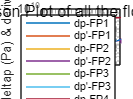

%Comparisson Plot
figure
sgtitle('Comparisson Plot of all the flow periods')
set (gca,'ydir','reverse');
subplot(1,1,1)

for g=1:1:flow_periods
    if rates(g)>0
        rateac=rates(g);
    else
        rateac=rates(g-1);
    end

    loglog(deltat(2:lengths(g), g), deltap(2:lengths(g),g)/(rateac), 'DisplayName','dp-FP'+string(g))
    hold on
    loglog(deltat(2:lengths(g)-1, g), derivative(1:(lengths(g)-2),g)/(rateac), 'DisplayName',"dp'-FP"+string(g))
end

grid on
legend()
xlabel('time (s)')
ylabel('deltap (Pa) & derivative')

# 7. Interpretation of all the FP

Using the following equations:

### Early Flow Times:


$$c_s =\frac{q\Delta t}{{\Delta p}^{\prime } \left(t\right)}$$


### Middle Flow Times:

- General:

            
$$k=\frac{\mu }{4\pi \textrm{mh}}$$


            
$$\alpha =\frac{2\ldotp 25k}{\mu c_t \phi {r_w }^2 }$$


- DD:

-     Pressure derivative Plot:

                
$$m=\frac{{\Delta p}^{\prime } \left(t\right)}{q}$$


                 
$$s=\frac{\frac{\Delta p\left(t\right)-{\Delta p}^{\prime } \left(t\right)}{\textrm{mq}}-\ln \alpha t+1}{2}\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp t=\textrm{MPMFT}\left(\textrm{middle}\;\textrm{point}\;\textrm{of}\;\textrm{MFT}\right)$$


-     Diagnostic Plot:

                
$$\textrm{mq}=\textrm{slope}\;\textrm{of}\;\textrm{the}\;\textrm{Middle}\;\textrm{Flow}\;\textrm{Time}\;\left(\textrm{MFT}\right)$$


               
$$b=\Delta p\left(t\right)-\textrm{mq}*\textrm{lnt}\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp t=\textrm{MPMFT}\left(\textrm{middle}\;\textrm{point}\;\textrm{of}\;\textrm{MFT}\right)$$


                 
$$s=\frac{\frac{b}{\textrm{mq}}-\ln \alpha }{2}$$


- BU:

-     Pressure derivative Plot:

                
$$m=\frac{{\Delta p}^{\prime } \left(t\right)}{q_{n-1} }$$


                 
$$s=\frac{\frac{\Delta p\left(t\right)}{mq_{n-1} }-\ln \alpha t}{2}\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp t=\textrm{MPMFT}\left(\textrm{middle}\;\textrm{point}\;\textrm{of}\;\textrm{MFT}\right)$$


-     Diagnostic Plot:

                
$$-mq_{n-1} =\textrm{slope}\;\textrm{of}\;\textrm{the}\;\textrm{Middle}\;\textrm{Flow}\;\textrm{Time}\;\left(\textrm{MFT}\right)$$


## Late Flow Times:


$$r_{\textrm{drainage}} =1\ldotp 5\sqrt{\frac{kt_{\textrm{IARF}} }{\mu c_t \phi }}$$


%Definition of early flow time (EFT, MFT and LFT) for each flow period
EFTi=[5 5 5 15];
EFTf=[20 20 20 70];
MFTi=[8000 5000 10000 5000];
MFTf=[15000 7000 15000 7000];
LFTi=[25000 35000 30000 40000];

%creation of the line of wbs, iarf (diagnostic and deriv) for the graphic
line_ws=zeros([max(lengths) flow_periods]); 
line_iarf_dg=zeros([max(lengths) flow_periods]);
line_iarf_deriv=zeros([max(lengths) flow_periods]);
for g=1:1:flow_periods
    %establish the flow periods time:
    EFT_i= EFTi(g);
    EFT_f=EFTf(g);
    MFT_i=MFTi(g);
    MFT_f=MFTf(g);
    LFT_i=LFTi(g);
    %detect the index of the value nearest to EFT_i (start of EFT)
    diff=abs(deltat(:,g)-EFT_i);
    val=min(diff);
    i_EFT_i=find(diff==val);
    %detect the index of the value nearest to EFT_f (end of EFT)
    diff=abs(deltat(:,g)-EFT_f);
    val=min(diff);
    i_EFT_f=find(diff==val);
    %detect the index of the value nearest to MFT_i (start of MFT)
    diff=abs(deltat(:,g)-MFT_i);
    val=min(diff);
    i_MFT_i=find(diff==val);
    %detect the index of the value nearest to MFT_i (end of MFT)
    diff=abs(deltat(:,g)-MFT_f);
    val=min(diff);
    i_MFT_f=find(diff==val);
    
    % Wellbore storage
    %detect the index of the deltat=1
    diff=(deltat(1:lengths(g),g)-1); 
    val=min(abs(diff));
    i_deltat_1=max(find(abs(diff)==val));
    %Interpolation if the value of deltat is lower and greater than 1...the
    %value of deltap corresponding to t=1 is almacenated in deltap_1
    if diff(i_deltat_1)<0
        if lnt(i_deltat_1,g)-lnt(i_deltat_1-1,g)==0
            deltap_1(g)=deltap(i_deltat_1,g);
        else
            a=(deltap(i_deltat_1,g)-deltap(i_deltat_1-1, g))/(deltat(i_deltat_1,g)-deltat(i_deltat_1-1,g));
            deltap_1(g)=deltap(i_deltat_1-1,g)+a*(1-deltat(i_deltat_1-1,g));
        end
       
    else
        if lnt(i_deltat_1+1,g)-lnt(i_deltat_1,g)==0
            deltap_1(g)=deltap(i_deltat_1,g);
        else
            a=(deltap(i_deltat_1+1,g)-deltap(i_deltat_1,g))/(deltat(i_deltat_1+1,g)-deltat(i_deltat_1,g));
            deltap_1(g)=deltap(i_deltat_1,g)+a*(1-deltat(i_deltat_1,g));
        end

    end

         

    if rates(g)>0 %Calculations for DD
        Cs(g)=rates(g)*Bo*mean(gradient(deltat(i_EFT_i:i_EFT_f,g), deltap(i_EFT_i:i_EFT_f,g))); %according to the equation
        line_ws(3:lengths(g), g)=deltat(3:lengths(g), g)*rates(g)*Bo/Cs(g); %creation of the line to graph WBS

        %Permeability & Skin from log log plot
        m_deriv_dd1=mean(derivative(i_MFT_i:i_MFT_f,g))/(rates(g)*Bo);
        k_deriv_dd1=(mu/(4*pi*m_deriv_dd1*h));
        k_deriv_mD_DD1=k_deriv_dd1*1.01325*10^15; %mD
        %s_deriv_dd1=mean(((deltap(round((i_MFT_i+i_MFT_f)/2,0),g))/(m_deriv_dd1*rates(g)*Bo))-log(2.25*k_deriv_dd1*timem(round((i_MFT_i+i_MFT_f)/2,0),g)/(mu*Ct*phi*rw^2)))/2;
        s_deriv_dd1=mean(((deltap(round((i_MFT_i+i_MFT_f)/2,0),g)-derivative(round((i_MFT_i+i_MFT_f)/2,0),g))/(m_deriv_dd1*rates(g)*Bo))-log(2.25*k_deriv_dd1*timem(round((i_MFT_i+i_MFT_f)/2,0),g)/(mu*Ct*phi*rw^2))+1)/2;

        %Permeability & Skin from diagnostic plot
        slope_dg_dd1=mean(gradient(deltap(i_MFT_i:i_MFT_f,g), lnt(i_MFT_i:i_MFT_f,g)));
        m_dg_dd1=slope_dg_dd1/(rates(g)*Bo);
        k_dg_dd1=(mu/(4*pi*m_dg_dd1*h));
        k_mD_DD1=k_dg_dd1*1.01325*10^15; %mD
        b=deltap(round((i_MFT_i+i_MFT_f)/2),g)-slope_dg_dd1*lnt(round((i_MFT_i+i_MFT_f)/2),g);
        s_dg_dd1=((b/(m_dg_dd1*rates(g)*Bo))-log(2.25*k_dg_dd1/(mu*Ct*phi*rw^2)))/2;
        line_iarf_dg(1:lengths(g)-1, g)=m_dg_dd1*rates(g)*Bo*(lnt(1:lengths(g)-1,g)+log(2.25*k_dg_dd1/(mu*Ct*phi*rw^2))+2*s_dg_dd1);
        line_iarf_deriv(3:lengths(g), g)=ones(length(deltat(3:lengths(g), g)), 1)*m_deriv_dd1*rates(g)*Bo;
    
    else %calculations for BU
        Cs(g)=rates(g-1)*Bo*mean(gradient(deltat(i_EFT_i:i_EFT_f,g), deltap(i_EFT_i:i_EFT_f,g)));
        line_ws(3:lengths(g), g)=deltat(3:lengths(g), g)*rates(g-1)*Bo/Cs(g);

        %Permeability & Skin from log log plot
        m_deriv_dd1=mean(derivative(i_MFT_i:i_MFT_f,g))/(rates(g-1)*Bo);
        k_deriv_dd1=(mu/(4*pi*m_deriv_dd1*h)); %in m2
        k_deriv_mD_DD1=k_deriv_dd1*1.01325*10^15; %convernting to mD
        %s_deriv_dd1=mean(((deltap(i_MFT_i:i_MFT_f,g)-derivative(i_MFT_i:i_MFT_f,g))/(m_deriv_dd1*rates(g-1)*Bo))-log(2.25*k_deriv_dd1/(mu*Ct*phi*rw^2))-lnt(i_MFT_i:i_MFT_f,g)+1)/2;
        s_deriv_dd1=mean(((deltap(round((i_MFT_i+i_MFT_f)/2,0),g))/(m_deriv_dd1*rates(g-1)*Bo))-log(2.25*k_deriv_dd1*timem(round((i_MFT_i+i_MFT_f)/2,0),g)/(mu*Ct*phi*rw^2)))/2;


        %Permeability from Horner plot
        lnST(:, g)=log(ST(:, g));
        slope_dg_dd1=-mean(gradient(pressm(i_MFT_i:i_MFT_f,g), lnST(i_MFT_i:i_MFT_f,g)));
        m_dg_dd1=slope_dg_dd1/(rates(g-1)*Bo);
        k_dg_dd1=(mu/(4*pi*m_dg_dd1*h));
        k_mD_DD1=k_dg_dd1*1.01325*10^15; %mD
        s_dg_dd1=-999;
        line_iarf_dg(1:lengths(g)-1, g)=Pi*100000-(m_dg_dd1*rates(g-1)*Bo*log(ST(1:lengths(g)-1, g)));
        line_iarf_deriv(3:lengths(g), g)=ones(length(deltat(3:lengths(g), g)), 1)*m_deriv_dd1*rates(g-1)*Bo;
    
    end
    %Calculation for LFT:
    drainage=1.5*((k_deriv_dd1*LFT_i/(mu*Ct*phi))^0.5);

    drain(g)=drainage;
    m_dg(g)=m_dg_dd1;
    m_deriv(g)=m_deriv_dd1;
    k_dg(g)=k_dg_dd1;
    k_deriv(g)=k_deriv_dd1;
    k_mD_dg(g)=k_mD_DD1;
    k_mD_deriv(g)=k_deriv_mD_DD1;
    s_der(g)=s_deriv_dd1;
    s_dg(g)=s_dg_dd1;
    
    alpha(g)=2.25*k_deriv_dd1/(mu*Ct*phi*rw^2);
end

# Plot all the FP with the solution

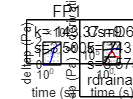

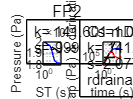

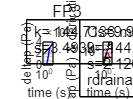

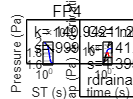

%Plotting
dim_dg=[.2 .5 .3 .3];
dim_der=[.6 .5 .3 .3];
for g=1:1:flow_periods
    figure
    
    set (gca,'ydir','reverse');
    sgtitle(strcat('FP', string(g)))
    subplot(1,2,1)
    strg_dg='k= '+string(k_mD_dg(g))+' mD'+newline+'s='+string(s_dg(g));
    strg_der='Cs='+string(Cs(g))+newline+'k= '+string(k_mD_deriv(g))+' mD'+newline+'s='+string(s_der(g))+newline+'rdrainage= '+string(drain(g))+' m';
    if rates(g)>0
        semilogx(deltat(2:lengths(g)-1, g), deltap(2:lengths(g)-1,g),'-b')
        %plot(log(deltat(2:lengths(g)-1, g)), deltap(2:lengths(g)-1,g),'-b')
        hold on
        semilogx(deltat(2:lengths(g)-1, g), line_iarf_dg(2:lengths(g)-1, g),'--black')
        grid on
        xlabel('time (s)')
        ylabel('deltap (Pa)')
        annotation('textbox', dim_dg,'String',strg_dg,'FitBoxToText','on');
    else
        semilogx(ST(1:lengths(g)-1, g), pressm(1:lengths(g)-1,g),'-b')
        hold on
        semilogx(ST(1:lengths(g)-1, g), line_iarf_dg(1:lengths(g)-1, g),'--black')
        annotation('textbox', dim_dg,'String',strg_dg,'FitBoxToText','on')
        grid on
        xlabel('ST (s)')
        ylabel('Pressure (Pa)')
    end
  
    
    subplot(1,2,2)
    loglog(deltat(2:lengths(g), g), deltap(2:lengths(g),g),'-b')
    if rates(g)>0 %only for DD because the diagnostic plot in BU use pressure not deltap
        hold on
        loglog(deltat(2:lengths(g), g), line_iarf_dg(2:lengths(g), g),'--black')
    end

    % hold on
    % loglog(deltat(2:lengths(g), g), line_iarf_dg(2:lengths(g), g),'--black')
    

    hold on
    loglog(deltat(3:lengths(g), g), derivative(1:(lengths(g)-2),g),'-r')
    hold on
    loglog(deltat(3:lengths(g), g), line_ws(3:lengths(g), g),'--black')
    hold on
    loglog(deltat(3:lengths(g), g), line_iarf_deriv(3:lengths(g), g),'--black')
    annotation('textbox', dim_der,'String',strg_der,'FitBoxToText','on')
    grid on
    xlabel('time (s)')
    ylabel('deltap (Pa) & derivative')
    ylim([(min(deltap(2:lengths(g),g))) (max(deltap(2:lengths(g),g)))*10]);

    
end